run parametros_y_especif.mlx

disp('Suponiendo el valor maximo en t = 0 de ')

Suponiendo el valor maximo en t = 0 de 


disp([num2str(Is_max),' A'])

2 A


Rs = linspace(1.02,1.32,5);
disp('Valores de Rs en Ohm')

Valores de Rs en Ohm


disp(Rs')

    1.0200
    1.0950
    1.1700
    1.2450
    1.3200



Rs_str = string(Rs)

Rs_str = 1×5 string array
    "1.02"    "1.095"    "1.17"    "1.245"    "1.32"



disp('Valor de inductancia Ld')

Valor de inductancia Ld


disp(Ld);

    0.0066



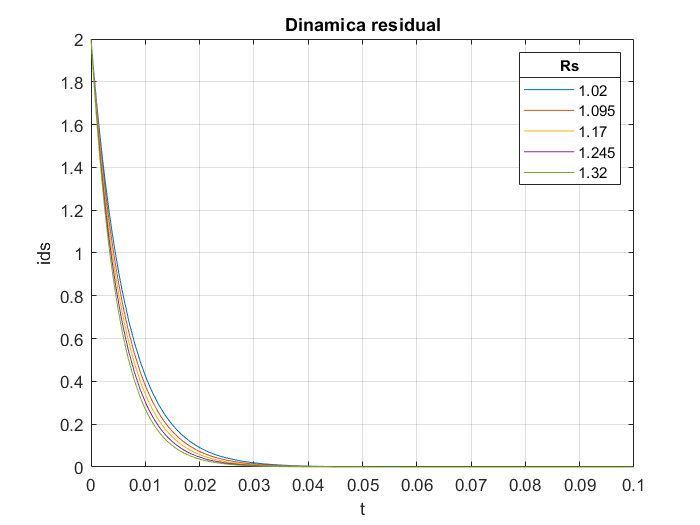


for a = Rs
    fplot(@(t) Is_max*exp(-(a/Ld)*t),[0,0.1])
    hold on
end
hold off
title('Dinamica residual')
lgd = legend(Rs_str);
title(lgd,'Rs');
xlabel('t');
ylabel('ids');
grid on;